# Hi

## Clear Workspace

clear
close all
clc


## Defining Our Dummy Radiation Pattern

%When we have a proper csv file for the radiation pattern 
%of our accepted horn, that file will replace the dummy data
data = readtable("Final_antenna_horn_gain_plot.csv");

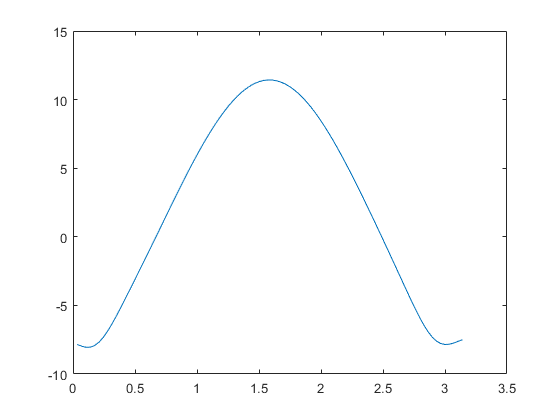

theta_prime = table2array(data(2:end, 3)) * pi / 180;
g_f = table2array(data(2:end, 4));
plot(theta_prime, g_f);

## Creating the Efficiency Equation

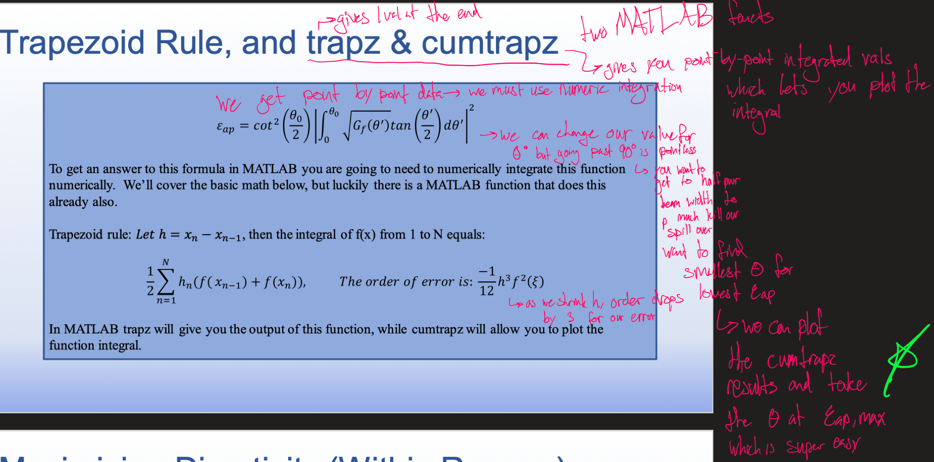

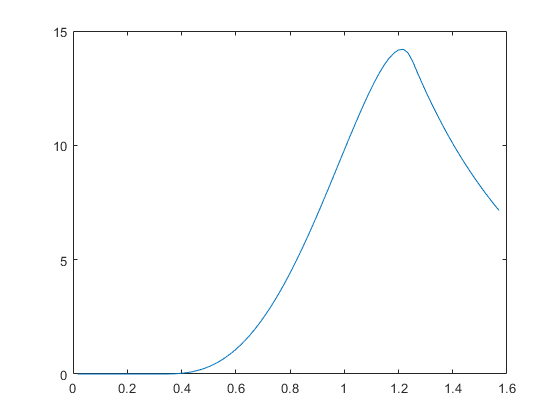

%We are going to get a radiation patern that is swept across some theta prime.
%We want to use the aperture efficiency equaiton (pictured above) to
%sweep across form 0 to different stopping angles (theta_o) until we find
%one that gives us the largest efficiency
%Note that theta_o represents the angle from the center of the dish to the
%edge of the dish

%Defining parts of the equation
stop_angle = 90;
integrand = real(sqrt(g_f).*tan(theta_prime/2));
theta_o = linspace(0,stop_angle * pi / 180,length(integrand)); %%0 to stop_angle
d0 = theta_o(2) - theta_o(1);

apperture_efficiency = zeros(1, length(theta_o));
integrand = integrand.';

for i = 1 : length(theta_o) %Creating different stopping angles from 0 to 90 degrees 
    integral = trapz(integrand(1 : i)) *d0;
    apperture_efficiency(i) = cot(theta_o(i) / 2)^2 * integral^2;
end

plot(linspace(0,stop_angle * pi / 180,length(apperture_efficiency)),abs(apperture_efficiency));


[max_efficiency, index_of_max_efficiency] = max(abs(apperture_efficiency))

max_efficiency = 14.1979

index_of_max_efficiency = 70

angle_of_max_effieciency = theta_o(index_of_max_efficiency)

angle_of_max_effieciency = 1.2178

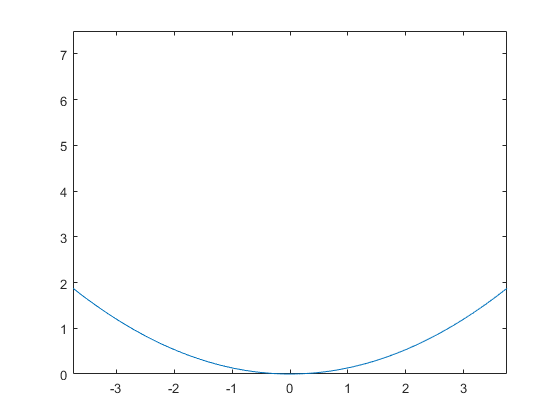

%%Solving for f and zo
d = 7.5; %%length of our reflector in feet
%%calculates focal length. change angle_of_max_effieciency to calc for other solutions
f = (d / 4) * cot(angle_of_max_effieciency / 2); 

zo = f - d^2 / (16 * f);

%%making matrixes
V = [1  -d/2 (-d/2)^2;
    1   0   0;
    1   d/2 (d/2)^2];

Y = [f - zo;
    0;
    f - zo];

C = V \ Y; %%note: \ is the operand for matrix division not /

x = -d / 2 : d / 100 : d / 2;
curve = C(3) * x.^2 + C(2) * x;
plot(x, curve);
xlim([-d / 2, d / 2]);
ylim([0 d]);